close all; clear; clc;

# CSv1 thrust curve #4

**file name**: CSv1_TM15d_20180824.mlx

**keywords:** continuous sweep, extra thrust curve (not primary or secondary)

**date of test:** 20180824

**file created by:** 20180830, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00228519349876825;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('CSv1_TM15d.mat');
time = CSv1_TM15d(:,1);                       % [sec]
PWM = CSv1_TM15d(:,2);                        % [micro sec]
Q = CSv1_TM15d(:,4);                          % [ft.lbf]
T = CSv1_TM15d(:,5);                          % [lbf]
Input_V = CSv1_TM15d(:,6);                    % [Volts]
Input_A = CSv1_TM15d(:,7);                    % [Amps]
rot_speed_rpm = CSv1_TM15d(:,8);              % [RPM]
% convert to rad for calculation purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = CSv1_TM15d(:,9);                     % [Watts]
P_out_W = CSv1_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = CSv1_TM15d(:,11);                 % [%]
Prop_Eff = CSv1_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = CSv1_TM15d(:,13);               % [lbf/Watts]  
ESC_Temp = CSv1_TM15d(:,14);                  % [F]
Motor_Temp = CSv1_TM15d(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

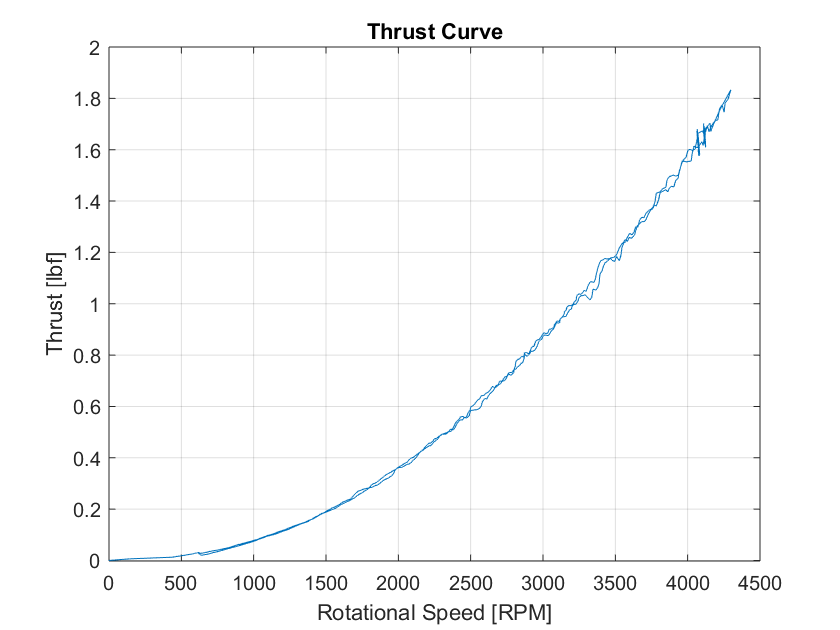

figure(1)
plot(rot_speed_rpm, T); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

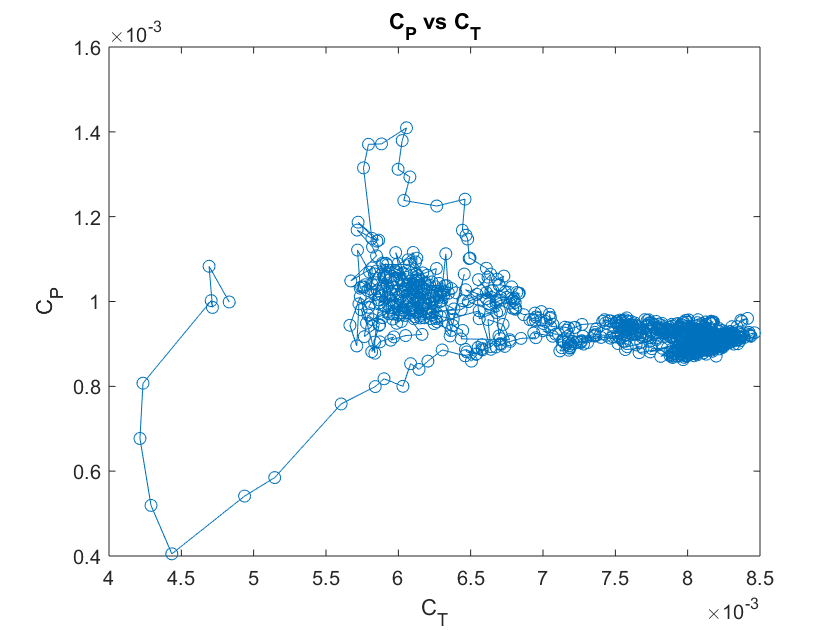


figure(2)
plot(C_T(23:1197), C_P(23:1197),'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P');

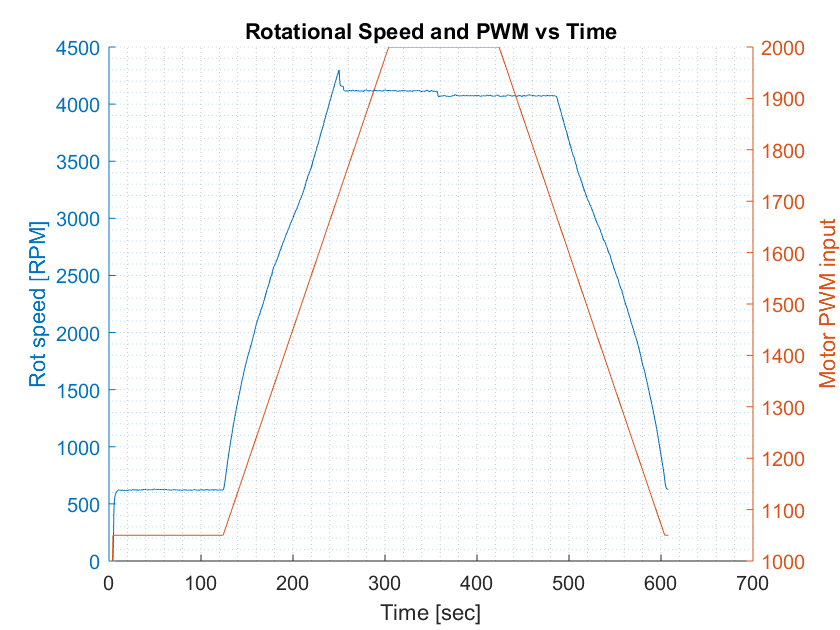


figure(3)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

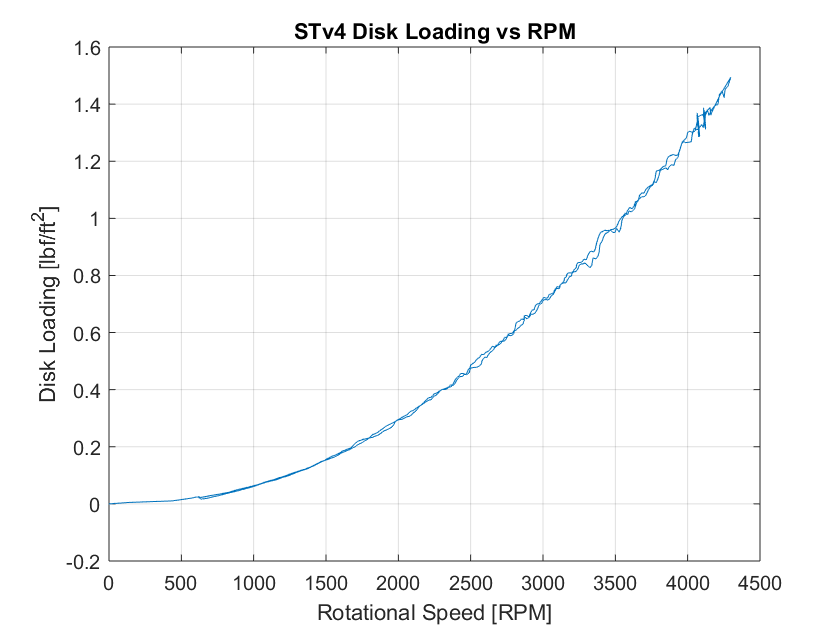


figure(4)
plot(rot_speed_rpm, disk_loading); title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

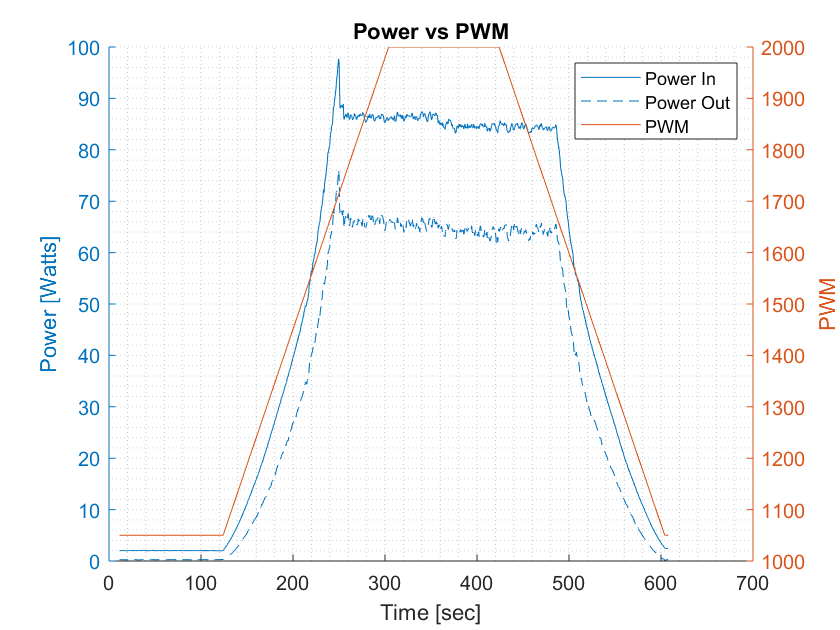



figure(5)
hold on
yyaxis left
plot(time(23:1197),P_in_W(23:1197), time(23:1197), P_out_W(23:1197));
ylabel('Power [Watts]');
legend('Power In', 'Power Out')
yyaxis right
plot(time(23:1197), PWM(23:1197), 'DisplayName','PWM');
ylabel('PWM');
title('Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

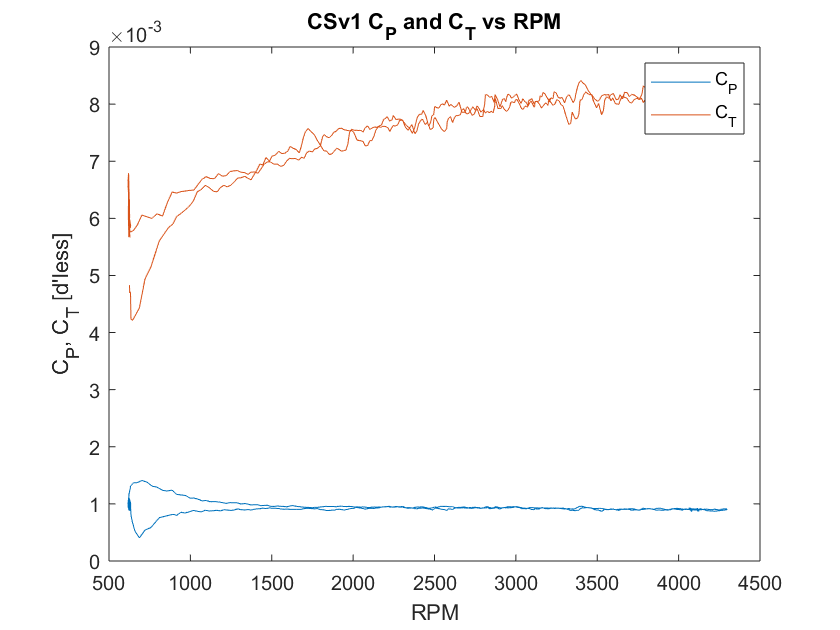


figure(6)
plot(rot_speed_rpm(23:1197), C_P(23:1197), rot_speed_rpm(23:1197), C_T(23:1197));
title('CSv1 C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('RPM'); ylabel("C_P, C_T [d'less]")

## Comparing Data to Momentum Theory

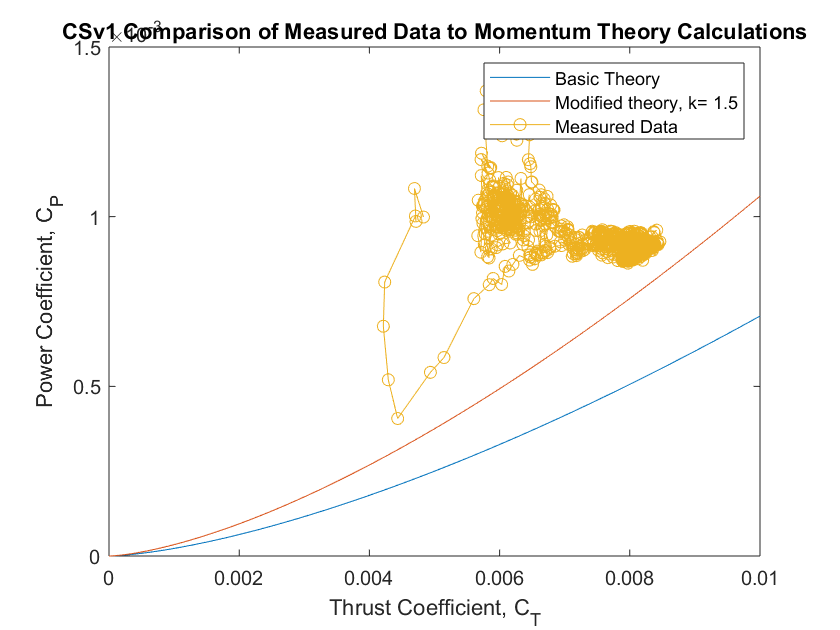

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T(23:1197), C_P(23:1197), 'o-');
title('CSv1 Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data');